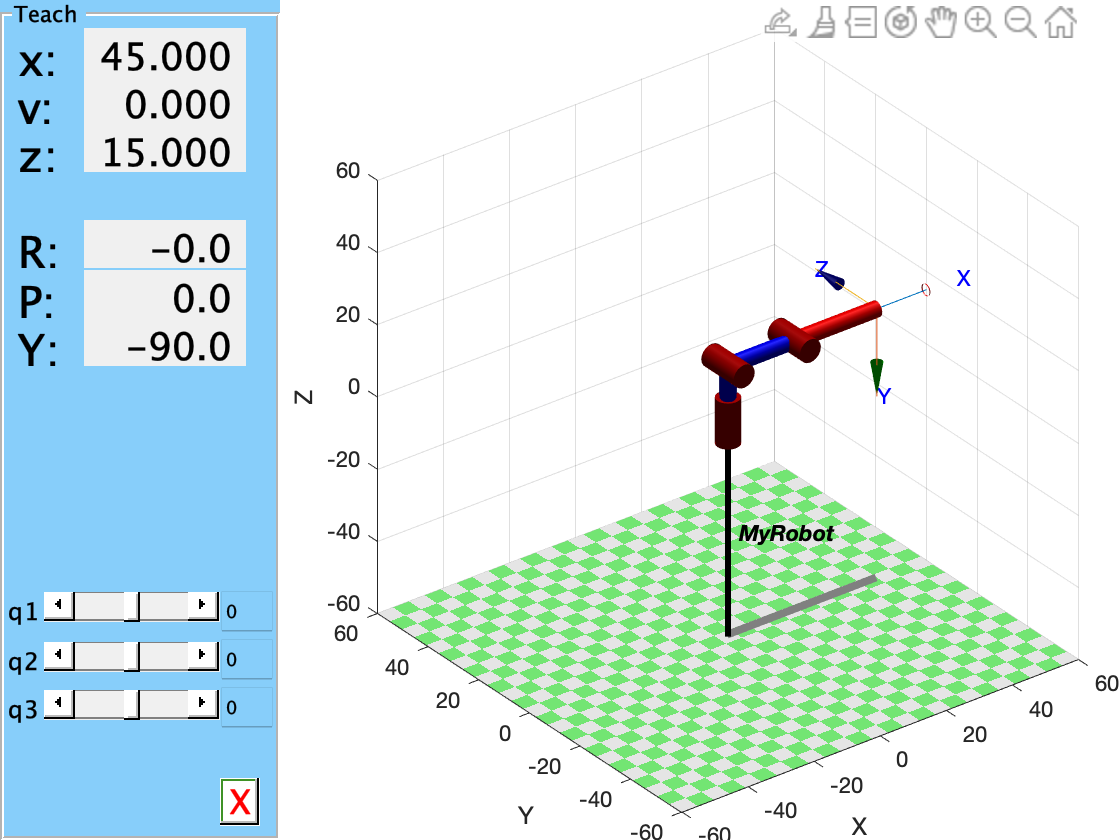

%Define links
%        theta  d  a  alpha
L1 = Link([0    15 0   -pi/2], 'standard');
L2 = Link([0    0 20   0], 'standard');
L3 = Link([0    0 25   0], 'standard');
%define the angles of each link
% L1.qlim = [deg2rad(-90) deg2rad(90)];
% L2.qlim = [deg2rad(-90) deg2rad(90)];
% L3.qlim = [deg2rad(-90) deg2rad(90)];
%join links
dobot = SerialLink([L1 L2 L3],'name','MyRobot');
dobot.teach()

dobot

 
dobot = 
 
MyRobot:: 3 axis, RRR, stdDH, slowRNE                            
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|         15|          0|    -1.5708|          0|
|  2|         q2|          0|         20|          0|          0|
|  3|         q3|          0|         25|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


or_tr = load("trajectory_mnist_test.mat");
trajectories = or_tr.predicted_tr

trajectories = trajectories(:,:,1) =

   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015  

digit = 4

digit = 4

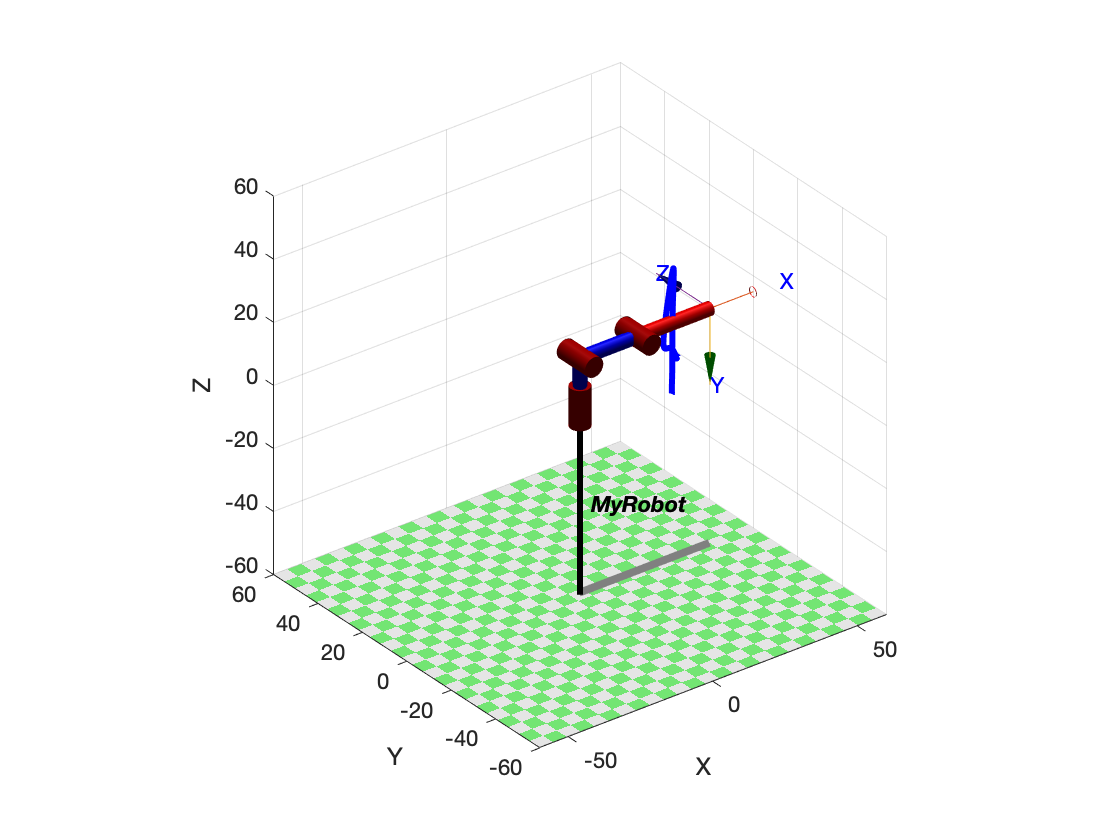

image_name = 'digit-11.gif';
figure(1)
C = trajectories(digit+1, :, :);
d = reshape(C, [301,3]);
points = d';
plot3(points(1,:),points(2,:),points(3,:),'-b','LineWidth',3);
hold on;
dobot.plot([0 0 0], 'trail', '-r');% show init robot 

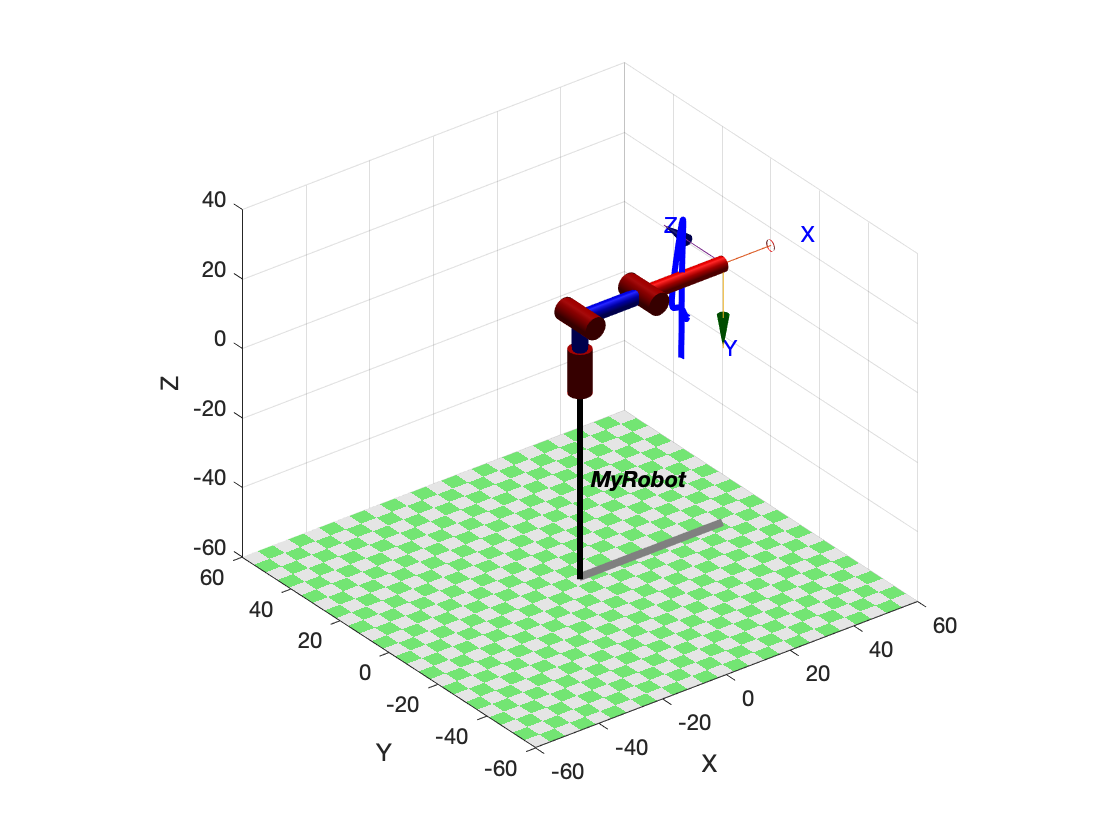

hold off;

%pionts tranform
points_t = points';
T = transl(points_t);
T_0 = transl(points_t(1,:));
T_1 = transl(points_t(301,:));

Q_0 = dobot.ikine(T_0,'mask',[1 1 1 0 0 0]);
Q_1 = dobot.ikine(T_1,'mask',[1 1 1 0 0 0]);
% mask vector
% do inverse kinematics
q = dobot.ikine(T,[0 0 0],'mask',[1 1 1 0 0 0]);

figure(3);
plot3(points(1,:),points(2,:),points(3,:),'-b','LineWidth',3);
opt = RTBPlot.plot_options(dobot, {'trail','*r'});
dobot.plot(q, 'trail', '.r','movie', image_name);

Animate: saving video --> digit-4.gif with profile 'GIF'
